%% =========================================================
%  LKA Kinematic Bicycle Model - Phase 1: State-Space Setup
%  MS-321 Modelling & Simulation | DE-45 Syndicate-A
%  Reference Vehicle: Toyota Corolla Altis X 1.6 (2026)
% ==========================================================

clc; clear; close all;

%% --- Vehicle Parameters ---
v   = 20;    % Longitudinal velocity [m/s]
L   = 2.7;   % Wheelbase [m]

%% --- State-Space Matrices ---
% States:  x = [e_y (m), psi_e (rad)]
% Input:   u = delta_f (front steering angle [rad])
% Output:  y = [e_y, psi_e]

A = [0,  v;   % e_y_dot    = v * psi_e
     0,  0];  % psi_e_dot  = (v/L) * delta_f  (no natural yaw term)

B = [0;        
     v/L];    % = 20/2.7 = 7.4074

C = eye(2);   % Both states are observed directly (monocular camera output)
D = zeros(2,1);


fprintf('A matrix:\n');

A matrix:


disp(A)

     0    20
     0     0




fprintf('B matrix:\n');

B matrix:


disp(B)

         0
    7.4074




fprintf('C matrix:\n');

C matrix:


disp(C)

     1     0
     0     1




fprintf('D matrix:\n');

D matrix:


disp(D)

     0
     0




%% --- Create State-Space Object ---
sys = ss(A, B, C, D);

%% --- Open-Loop Eigenvalues (Poles) ---
poles = eig(A);
fprintf('Open-Loop Eigenvalues (Poles):\n');

Open-Loop Eigenvalues (Poles):


disp(poles)

     0
     0





%% --- Controllability & Observability Check ---
Co = ctrb(A, B);
Ob = obsv(A, C);

% 1. Define the curvature input matrix (affects only the heading state negatively)
B_curve = [0; -1]; 

% 2. Augment the B and D matrices to accept two inputs [steering, curvature]
B_aug = [B, B_curve]; 
D_aug = zeros(2, 2);

fprintf('\nControllability Matrix rank : %d (should be 2)\n', rank(Co));


Controllability Matrix rank : 2 (should be 2)


fprintf('Observability Matrix rank   : %d (should be 2)\n', rank(Ob));

Observability Matrix rank   : 2 (should be 2)



if rank(Co) == 2
    fprintf('>> System is FULLY CONTROLLABLE. LQR design is valid.\n');
else
    fprintf('>> WARNING: System is NOT controllable.\n');
end

>> System is FULLY CONTROLLABLE. LQR design is valid.



if rank(Ob) == 2
    fprintf('>> System is FULLY OBSERVABLE. State feedback is valid.\n');
else
    fprintf('>> WARNING: System is NOT observable.\n');
end

>> System is FULLY OBSERVABLE. State feedback is valid.


## --- Solve Algebraic Riccati Equation (ARE) ---

Q = [100,  0;
     0,   10];

R = [1];

[K, P, poles_cl] = lqr(A, B, Q, R);

fprintf('--------------------------------------------\n');

--------------------------------------------


fprintf('Riccati Matrix P (solution to ARE):\n');

Riccati Matrix P (solution to ARE):


disp(P)

    4.0000    1.3500
    1.3500    1.0800




fprintf('Optimal Feedback Gain K:\n');

Optimal Feedback Gain K:


disp(K)

   10.0000    8.0000



fprintf('  K(1) - Lateral error gain  (e_y)   : %.4f rad/m\n',   K(1));

  K(1) - Lateral error gain  (e_y)   : 10.0000 rad/m


fprintf('  K(2) - Heading error gain  (psi_e) : %.4f rad/rad\n', K(2));

  K(2) - Heading error gain  (psi_e) : 8.0000 rad/rad



%% --- Closed-Loop System ---
A_cl = A - B*K;   % Now K is (1x2), B is (2x1) -> B*K is (2x2) -- correct

fprintf('\n--------------------------------------------\n');


--------------------------------------------


fprintf('Closed-Loop A matrix (A - B*K):\n');

Closed-Loop A matrix (A - B*K):


disp(A_cl)

         0   20.0000
  -74.0741  -59.2593




%% --- Open-Loop vs Closed-Loop Poles ---
poles_ol = eig(A);

fprintf('Open-Loop Poles:\n');

Open-Loop Poles:


disp(poles_ol)

     0
     0




fprintf('Closed-Loop Poles (from lqr):\n');

Closed-Loop Poles (from lqr):


disp(poles_cl)

 -29.6296 +24.5676i
 -29.6296 -24.5676i




%% --- Stability Check ---
if all(real(poles_cl) < 0)
    fprintf('>> System is ASYMPTOTICALLY STABLE under LQR.\n');
    fprintf('>> All closed-loop poles in the left-half plane.\n');
else
    fprintf('>> WARNING: Unstable. Re-check Q and R matrices.\n');
end

>> System is ASYMPTOTICALLY STABLE under LQR.


>> All closed-loop poles in the left-half plane.



%% --- Settling Time Estimate ---
fastest_pole = max(real(poles_cl));
settling_time = 4 / abs(fastest_pole);
fprintf('\n--------------------------------------------\n');


--------------------------------------------


fprintf('Closed-Loop Performance Estimates:\n');

Closed-Loop Performance Estimates:


fprintf('  Fastest pole              : %.4f\n', fastest_pole);

  Fastest pole              : -29.6296


fprintf('  Approx. settling time     : %.2f s  (4/|fastest pole|)\n', settling_time);

  Approx. settling time     : 0.13 s  (4/|fastest pole|)


## Phase 3

%% --- Parameters ---
v = 20;
L = 2.7;

A = [0,  v;
     0,  0];

B = [0;
     v/L];

C = eye(2);
D = zeros(2,1);

Q = [100, 0;
     0,  10];
R = 1;

[K, P, poles_cl] = lqr(A, B, Q, R);

%% --- Initial Conditions ---
x0 = [0.3;    % e_y   = 0.3 m  (lateral offset)
      0.05];  % psi_e = 0.05 rad (heading error ~2.9 deg)

%% --- Simulation Time ---
t_end = 3;    % seconds (same as dynamic model Scenario 1)

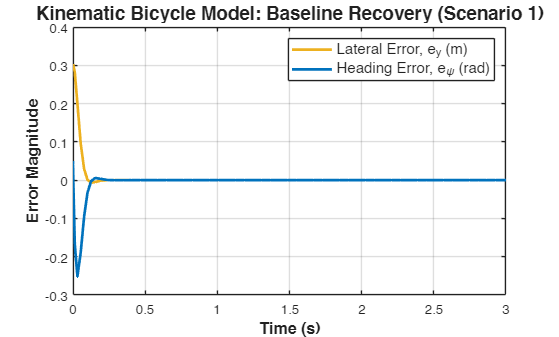

%% Plotting Kinematic Model Results
% Ensure you have run the Simulink model first so the 'out' variable exists 
% in your workspace.

% 1. Extract data from the Timeseries object
time = out.kinematic_states.Time;
e_y = out.kinematic_states.Data(:, 1);    % First column is Lateral Error
e_psi = out.kinematic_states.Data(:, 2);  % Second column is Heading Error

% 2. Initialize the Figure
figure('Name', 'Kinematic Baseline Recovery', 'Color', 'white');

% 3. Plot the States
plot(time, e_y, 'LineWidth', 2, 'Color', '#EDB120'); % Yellow-ish for e_y
hold on;
plot(time, e_psi, 'LineWidth', 2, 'Color', '#0072BD'); % Blue for e_psi

% 4. Format the Graph for the Report
grid on;
title('Kinematic Bicycle Model: Baseline Recovery (Scenario 1)', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Error Magnitude', 'FontSize', 12, 'FontWeight', 'bold');

% 5. Add a clear legend
legend('Lateral Error, e_y (m)', 'Heading Error, e_{\psi} (rad)', ...
       'Location', 'northeast', 'FontSize', 11);

% Optional: Set axis limits if you want to zoom in on the settling time
% xlim([0 0.5]); 
% ylim([-0.3 0.35]);

hold off;

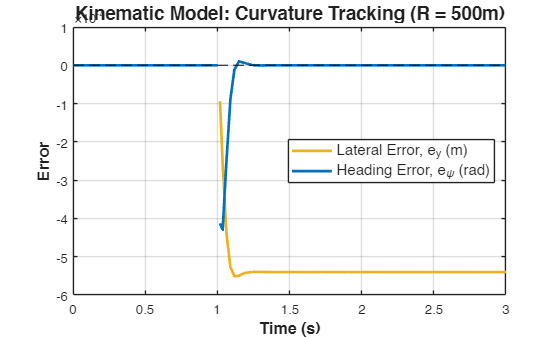

%% Plotting Kinematic Model - Scenario 3 (Curvature Tracking)

% 1. Extract data
time = out.kinematic_states_2.Time;
e_y = out.kinematic_states_2.Data(:, 1);   
e_psi = out.kinematic_states_2.Data(:, 2); 

% 2. Initialize the Figure
figure('Name', 'Kinematic Curvature Tracking', 'Color', 'white');

% 3. Plot the States
plot(time, e_y, 'LineWidth', 2, 'Color', '#EDB120'); 
hold on;
plot(time, e_psi, 'LineWidth', 2, 'Color', '#0072BD'); 

% 4. Format the Graph
grid on;
title('Kinematic Model: Curvature Tracking (R = 500m)', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Error', 'FontSize', 12, 'FontWeight', 'bold');

% 5. Add Reference Line for Zero
yline(0, 'k--', 'LineWidth', 1);

legend('Lateral Error, e_y (m)', 'Heading Error, e_{\psi} (rad)', ...
       'Location', 'east', 'FontSize', 11);

hold off;


% 6. Display the steady-state error in the command window
fprintf('Steady-State Lateral Error: %.4f m\n', e_y(end));

Steady-State Lateral Error: -0.0005 m
